# `Computer Assignment 1`

# Part 1:

First the fist datas were loaded (the 26th row was chosen to be analysed)

datas = ["v1.mat", "v2.mat", "v3.mat", "v4.mat"];
signals = zeros(4, 1600);
for i = 1 : 4
    v = load(datas(i));
    signals(i, :) = v.val(26,:);
end

The signals were plotted in time domain

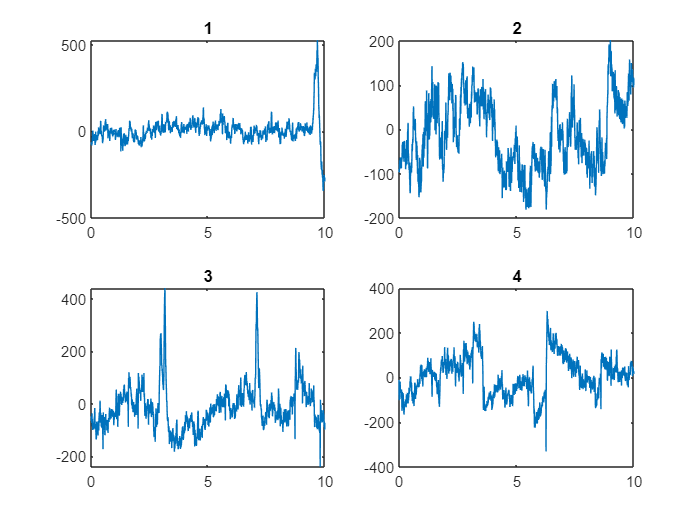

L = 1600;
time = 10;
Fs = L / time;
t = (0 : L-1) ./ Fs;

figure(1);
for i = 1 : 4
    subplot(2,2,i);
    plot(t,signals(i,:));
    title(i);
end

And then the datas were plotted in frequency domain

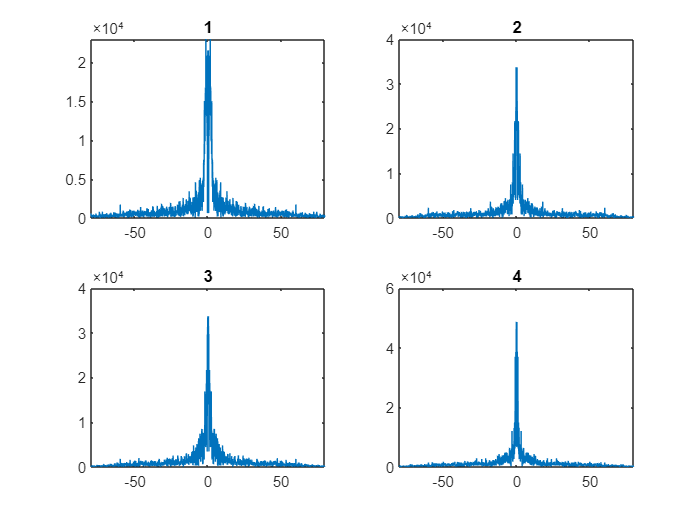

for i = 1 : 4
    signals_fft(i,:) = fftshift(fft(signals(i,:))); 
end
freq = Fs*linspace(-0.5, 0.5, length(signals_fft));

figure(2);
for i = 1 : 4
    subplot(2,2,i);
    plot(freq,abs(signals_fft(i, :)));
    title(i);
    xlim([-max(freq) max(freq)]);
end

Next, different brain signals were extracted from them, using their different frequency ranges

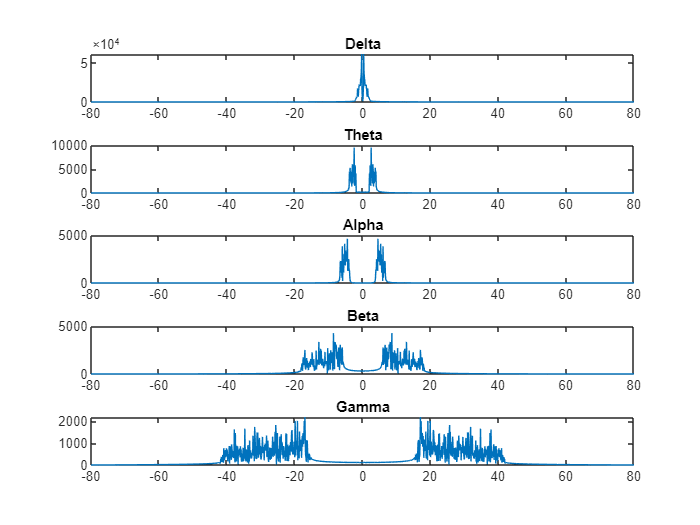

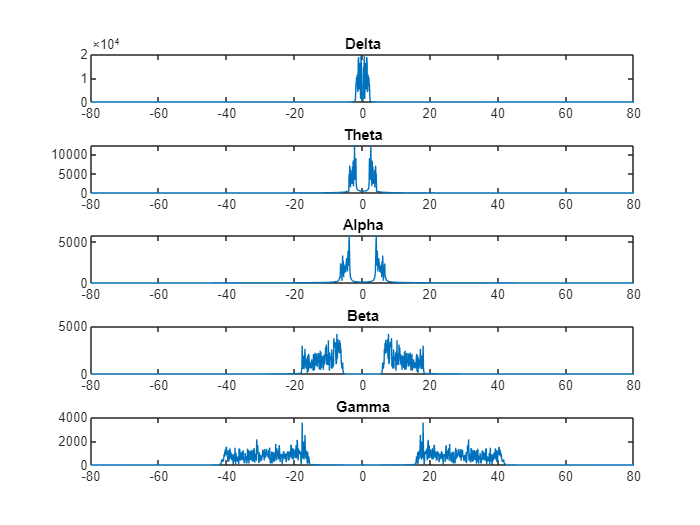

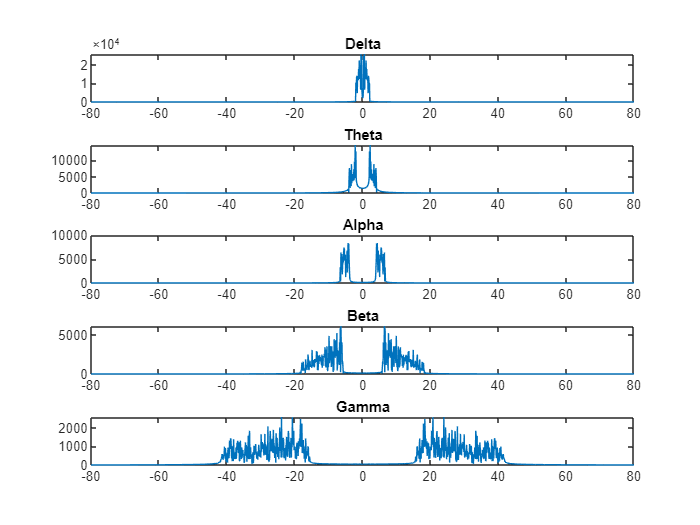

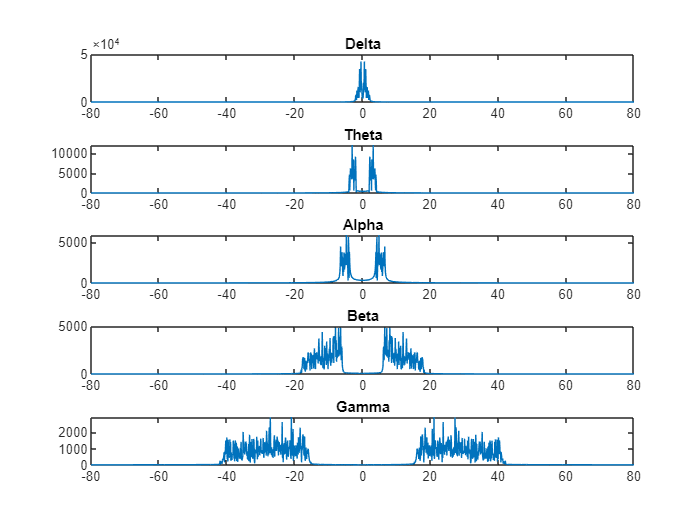

Delta_freq = [0.5 , 4]./Fs;
Theta_freq = [4 , 8]./Fs;
Alpha_freq = [8 , 13]./Fs;
Beta_freq = [13 , 35]./Fs;
Gamma_freq = [35 , Fs/2]./Fs;


for i = 1 : 4
    Delta(i,:)=bandpass(signals(i,:),Delta_freq);
    Theta(i,:)=bandpass(signals(i,:),Theta_freq);
    Alpha(i,:)=bandpass(signals(i,:),Alpha_freq);
    Beta(i,:)=bandpass(signals(i,:),Beta_freq);
    Gamma(i,:)=bandpass(signals(i,:),Gamma_freq);
end

for i = 1 : 4
    figure(i+2)
    subplot(5,1,1);
    plot(freq, abs(fftshift(fft(Delta(i,:)))));
    title("Delta")
    subplot(5,1,2);
    plot(freq, abs(fftshift(fft(Theta(i,:)))));
    title("Theta");
    subplot(5,1,3);
    plot(freq, abs(fftshift(fft(Alpha(i,:)))));
    title("Alpha");
    subplot(5,1,4);
    plot(freq, abs(fftshift(fft(Beta(i,:)))));
    title("Beta");
    subplot(5,1,5);
    plot(freq, abs(fftshift(fft(Gamma(i,:)))));
    title("Gamma");
    
end

Then the brain signals were also shown in time domain

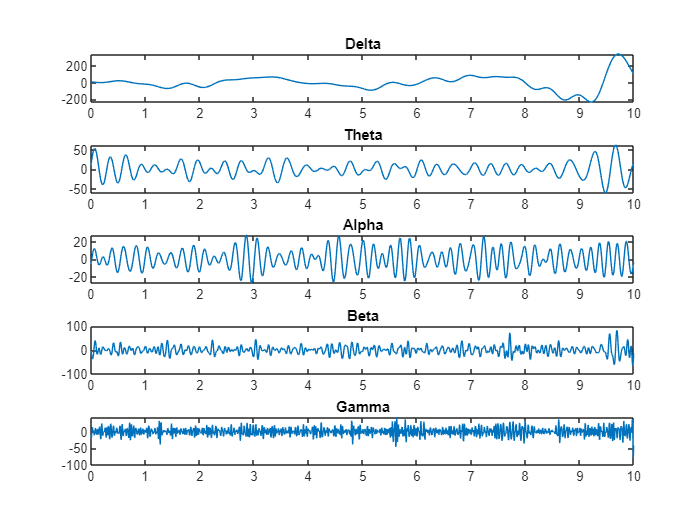

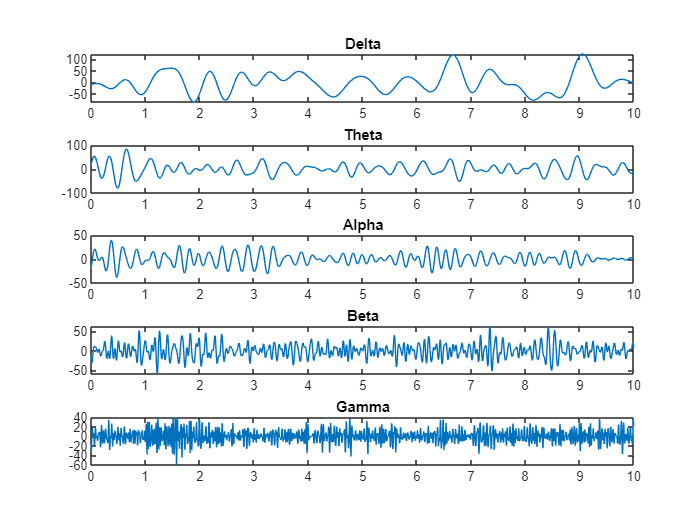

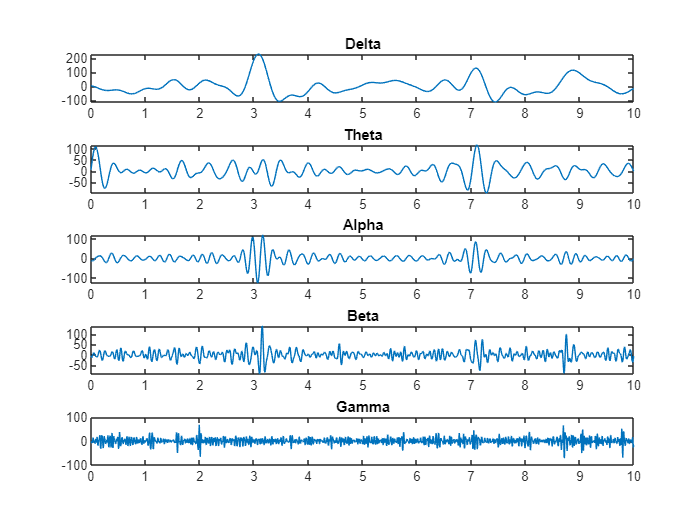

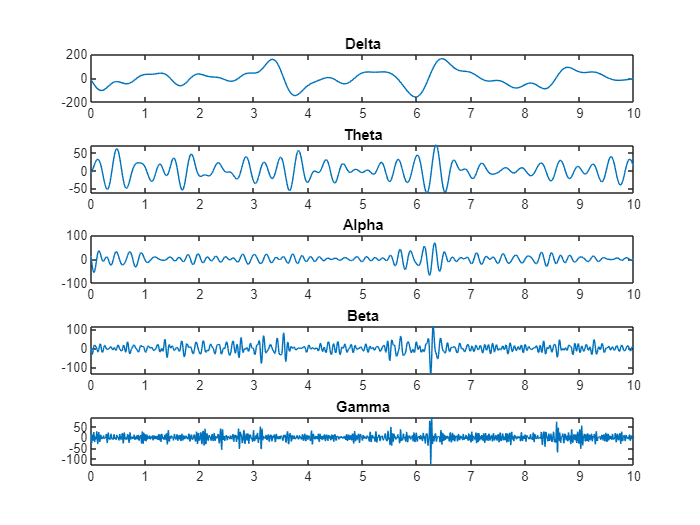

for i = 1 : 4
    figure(i+6);
    subplot(5,1,1);
    plot(t, Delta(i,:));
    title("Delta");
    subplot(5,1,2);
    plot(t, Theta(i,:));
    title("Theta");
    subplot(5,1,3);
    plot(t, Alpha(i,:));
    title("Alpha");
    subplot(5,1,4);
    plot(t, Beta(i,:));
    title("Beta");
    subplot(5,1,5);
    plot(t, Gamma(i,:));
    title("Gamma");
end

Since the Delta signals have a really high amplitude, they're not a reliable source of deduction for the stages of brain. But with comparing other signal waves, we can assume that:

- The first person is in "Problem Solving" stage (considering high levels of Beta signals)

- The second person is in "Meditaion and Creativity" or "Deep Sleep" stage (considering high levels of Theta and Delta signals)

- The third person is in "Deep Sleep" stage and probably dreaming (considering extremely high levels of Delta signals and also other signals being high)

- the forth person could also be dreaming in "Deep Sleep" stage (for the same reasons) but also could be in "Relaxed Reflection" (considering high levels of Alpha signal)

It should be noted that these concolusions are based on comparing brain signals of different people, which isn't a reliable techniqe; because people's brains function differently and don't give the same results in same conditions.

# Part 2

The datas for this part were loaded

load("data.mat");

fs = stage0.Fs(1);
Ts = 1/fs;

## **Analysing the known datas**

First each of the 3 known datas were plotted both in time and frequency domain

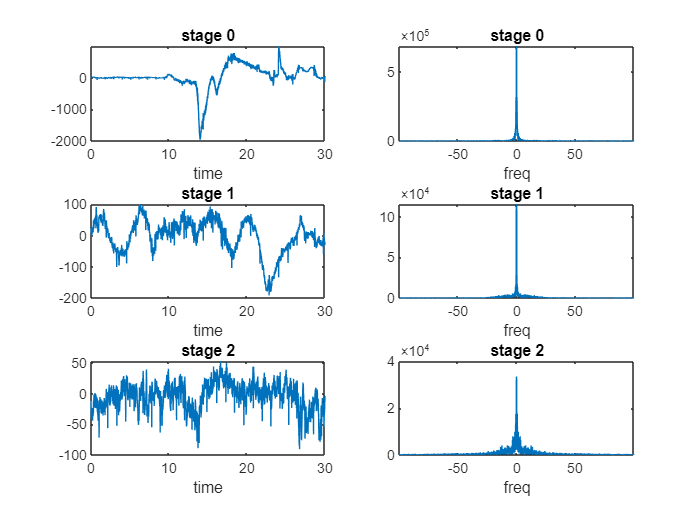

L0 = stage0.Duration;
L1 = stage1.Duration;
L2 = stage2.Duration;

t0 = (0 : L0-1)*Ts;
t1 = (0 : L1-1)*Ts;
t2 = (0 : L2-1)*Ts;

signal0 = stage0.Data(:,2);
signal1 = stage1.Data(:,2);
signal2 = stage2.Data(:,2);

%calculating fft
signal0_fft = fftshift(fft(signal0));
signal1_fft = fftshift(fft(signal1));
signal2_fft = fftshift(fft(signal2));

freq0 = fs*linspace(-0.5, 0.5, length(signal0_fft));
freq1 = fs*linspace(-0.5, 0.5, length(signal1_fft));
freq2 = fs*linspace(-0.5, 0.5, length(signal2_fft));


figure();

%stage 0 in time and freq domain
subplot(3,2,1);
plot(t0, signal0);
title("stage 0");
xlabel('time');
subplot(3,2,2);
plot(freq0,abs(signal0_fft));
title("stage 0");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

%stage 1 in time and freq domain
subplot(3,2,3);
plot(t1, signal1);
title("stage 1");
xlabel('time');
subplot(3,2,4);
plot(freq1,abs(signal1_fft));
title("stage 1");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

%stage 2 in time and freq domain
subplot(3,2,5);
plot(t2, signal2);
title("stage 2");
xlabel('time');
subplot(3,2,6);
plot(freq2,abs(signal2_fft));
title("stage 2");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

then each state was analysed seperatly and different brain signals were extracted from each of them

### stage 0:

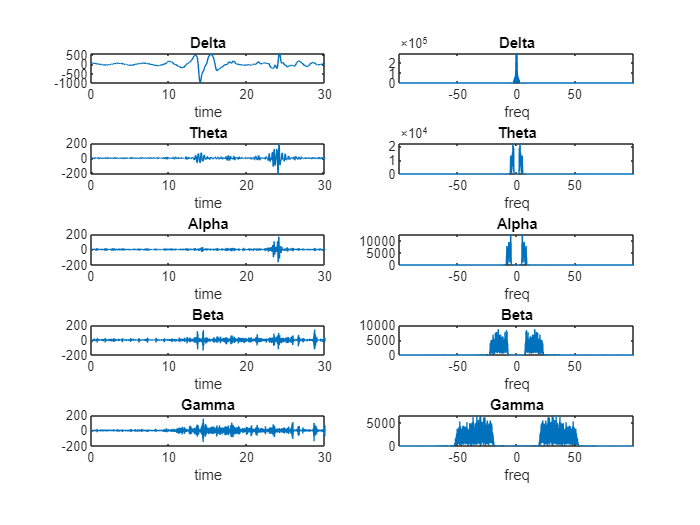

Delta0=bandpass(signal0,Delta_freq);
Theta0=bandpass(signal0,Theta_freq);
Alpha0=bandpass(signal0,Alpha_freq);
Beta0=bandpass(signal0,Beta_freq);
Gamma0=bandpass(signal0,Gamma_freq);

figure();

subplot(5,2,1);
plot(t0, Delta0);
title("Delta");
xlabel('time');
subplot(5,2,2);
plot(freq0,abs(fftshift(fft(Delta0))));
title("Delta");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

subplot(5,2,3);
plot(t0, Theta0);
title("Theta");
xlabel('time');
subplot(5,2,4);
plot(freq0,abs(fftshift(fft(Theta0))));
title("Theta");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

subplot(5,2,5);
plot(t0, Alpha0);
title("Alpha");
xlabel('time');
subplot(5,2,6);
plot(freq0,abs(fftshift(fft(Alpha0))));
title("Alpha");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

subplot(5,2,7);
plot(t0, Beta0);
title("Beta");
xlabel('time');
subplot(5,2,8);
plot(freq0,abs(fftshift(fft(Beta0))));
title("Beta");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

subplot(5,2,9);
plot(t0, Gamma0);
title("Gamma");
xlabel('time');
subplot(5,2,10);
plot(freq0,abs(fftshift(fft(Gamma0))));
title("Gamma");
xlim([-max(freq0) max(freq0)]);
xlabel('freq');

### stage 1:

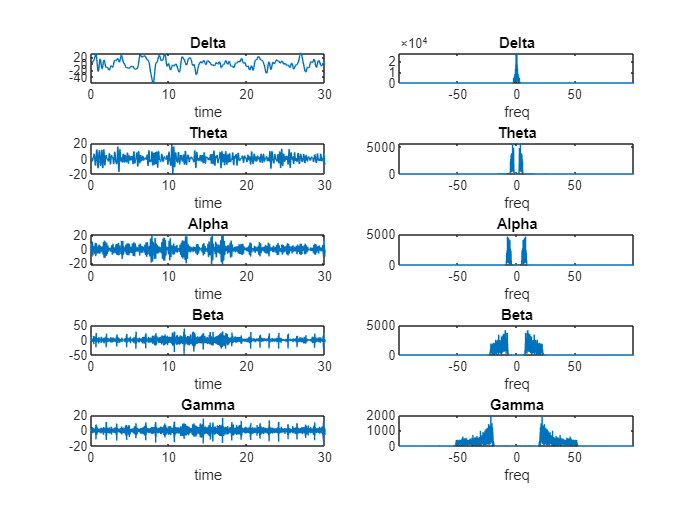

Delta1=bandpass(signal1,Delta_freq);
Theta1=bandpass(signal1,Theta_freq);
Alpha1=bandpass(signal1,Alpha_freq);
Beta1=bandpass(signal1,Beta_freq);
Gamma1=bandpass(signal1,Gamma_freq);

figure();

subplot(5,2,1);
plot(t1, Delta1);
title("Delta");
xlabel('time');
subplot(5,2,2);
plot(freq1,abs(fftshift(fft(Delta1))));
title("Delta");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

subplot(5,2,3);
plot(t1, Theta1);
title("Theta");
xlabel('time');
subplot(5,2,4);
plot(freq1,abs(fftshift(fft(Theta1))));
title("Theta");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

subplot(5,2,5);
plot(t1, Alpha1);
title("Alpha");
xlabel('time');
subplot(5,2,6);
plot(freq1,abs(fftshift(fft(Alpha1))));
title("Alpha");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

subplot(5,2,7);
plot(t1, Beta1);
title("Beta");
xlabel('time');
subplot(5,2,8);
plot(freq1,abs(fftshift(fft(Beta1))));
title("Beta");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

subplot(5,2,9);
plot(t1, Gamma1);
title("Gamma");
xlabel('time');
subplot(5,2,10);
plot(freq1,abs(fftshift(fft(Gamma1))));
title("Gamma");
xlim([-max(freq1) max(freq1)]);
xlabel('freq');

### stage 2:

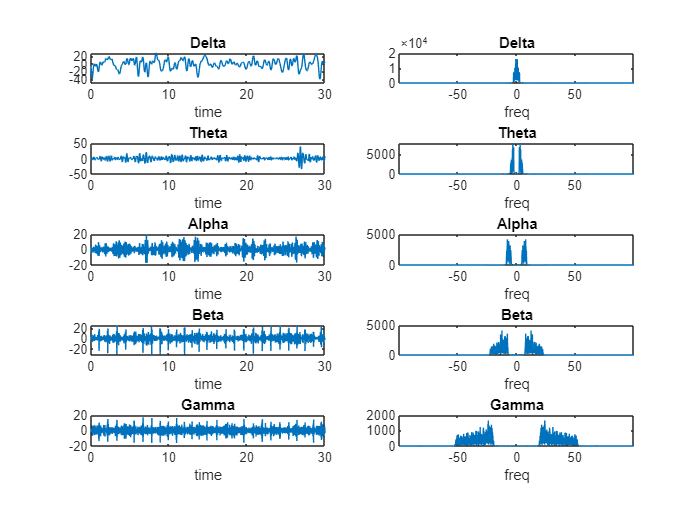

Delta2=bandpass(signal2,Delta_freq);
Theta2=bandpass(signal2,Theta_freq);
Alpha2=bandpass(signal2,Alpha_freq);
Beta2=bandpass(signal2,Beta_freq);
Gamma2=bandpass(signal2,Gamma_freq);

figure();

subplot(5,2,1);
plot(t2, Delta2);
title("Delta");
xlabel('time');
subplot(5,2,2);
plot(freq2,abs(fftshift(fft(Delta2))));
title("Delta");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

subplot(5,2,3);
plot(t2, Theta2);
title("Theta");
xlabel('time');
subplot(5,2,4);
plot(freq2,abs(fftshift(fft(Theta2))));
title("Theta");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

subplot(5,2,5);
plot(t2, Alpha2);
title("Alpha");
xlabel('time');
subplot(5,2,6);
plot(freq2,abs(fftshift(fft(Alpha2))));
title("Alpha");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

subplot(5,2,7);
plot(t2, Beta2);
title("Beta");
xlabel('time');
subplot(5,2,8);
plot(freq2,abs(fftshift(fft(Beta2))));
title("Beta");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

subplot(5,2,9);
plot(t2, Gamma2);
title("Gamma");
xlabel('time');
subplot(5,2,10);
plot(freq2,abs(fftshift(fft(Gamma2))));
title("Gamma");
xlim([-max(freq2) max(freq2)]);
xlabel('freq');

In stage 0, the Theta waves are high and then their amplitude decreases along with the others exept for delta waves. The Delta waves also increase when mind shifts from stage 1 to stage 2 of sleep.

## **Analysing the to_find datas:**

These datas are also plotted in both time and frequency domains

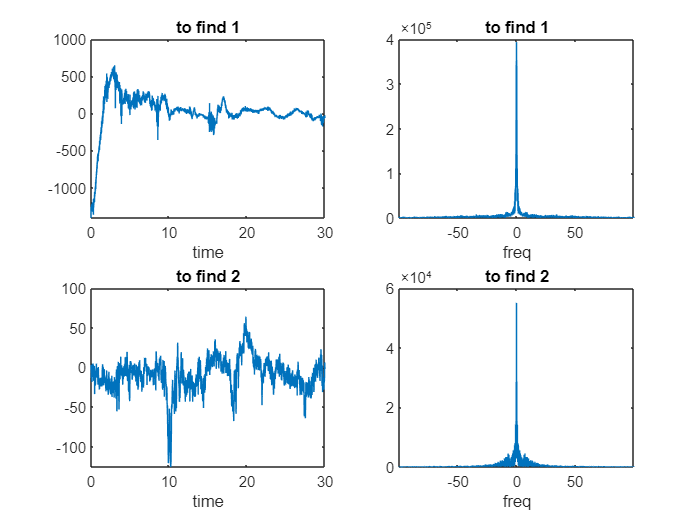

L_find = to_find.Duration;
t_find = (0 : L_find-1)*Ts;

find1 = to_find.Data(:,1);
find2 = to_find2.Data(:,1);

tofind1_fft = fftshift(fft(find1));
tofind2_fft = fftshift(fft(find2));

freqfind1 = fs*linspace(-0.5, 0.5, length(tofind1_fft));
freqfind2 = fs*linspace(-0.5, 0.5, length(tofind2_fft));

figure();
subplot(2,2,1);
plot(t_find, find1);
title("to find 1");
xlabel('time')
subplot(2,2,2);
plot(freqfind1,abs(tofind1_fft));
title("to find 1");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

subplot(2,2,3);
plot(t_find, find2);
title("to find 2");
xlabel('time')
subplot(2,2,4);
plot(freqfind2,abs(tofind2_fft));
title("to find 2");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

Then different brain waves are extracted from each of them

### to find 1

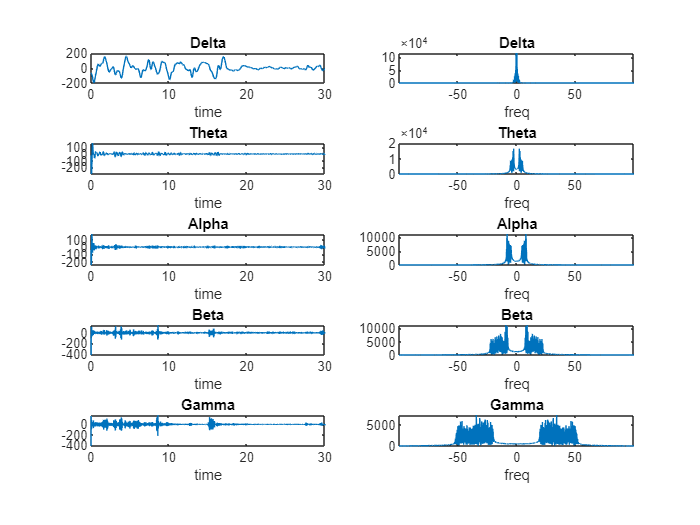

Delta_find1=bandpass(find1,Delta_freq);
Theta_find1=bandpass(find1,Theta_freq);
Alpha_find1=bandpass(find1,Alpha_freq);
Beta_find1=bandpass(find1,Beta_freq);
Gamma_find1=bandpass(find1,Gamma_freq);

figure();

subplot(5,2,1);
plot(t_find, Delta_find1);
title("Delta");
xlabel('time');
subplot(5,2,2);
plot(freqfind1,abs(fftshift(fft(Delta_find1))));
title("Delta");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

subplot(5,2,3);
plot(t_find, Theta_find1);
title("Theta");
xlabel('time');
subplot(5,2,4);
plot(freqfind1,abs(fftshift(fft(Theta_find1))));
title("Theta");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

subplot(5,2,5);
plot(t_find, Alpha_find1);
title("Alpha");
xlabel('time');
subplot(5,2,6);
plot(freqfind1,abs(fftshift(fft(Alpha_find1))));
title("Alpha");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

subplot(5,2,7);
plot(t_find, Beta_find1);
title("Beta");
xlabel('time');
subplot(5,2,8);
plot(freqfind1,abs(fftshift(fft(Beta_find1))));
title("Beta");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

subplot(5,2,9);
plot(t_find, Gamma_find1);
title("Gamma");
xlabel('time');
subplot(5,2,10);
plot(freqfind1,abs(fftshift(fft(Gamma_find1))));
title("Gamma");
xlim([-max(freqfind1) max(freqfind1)]);
xlabel('freq');

since the Theta waves have high levels of amplitude in this signal, this person could be in stage 0 of sleeping.

### to find 2

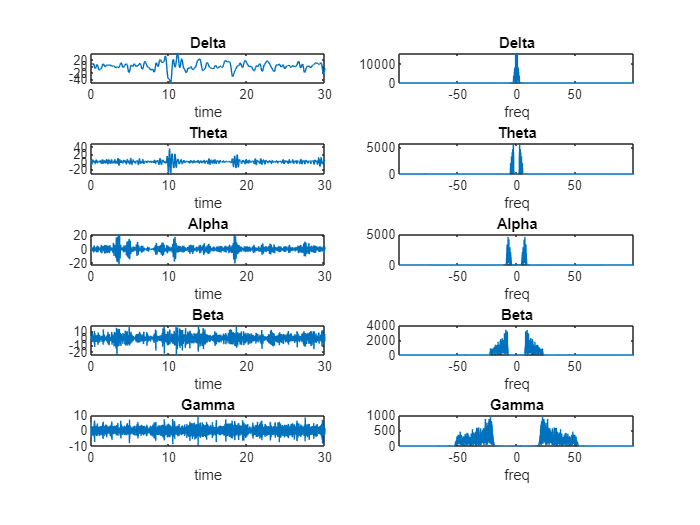

Delta_find2=bandpass(find2,Delta_freq);
Theta_find2=bandpass(find2,Theta_freq);
Alpha_find2=bandpass(find2,Alpha_freq);
Beta_find2=bandpass(find2,Beta_freq);
Gamma_find2=bandpass(find2,Gamma_freq);

figure();

subplot(5,2,1);
plot(t_find, Delta_find2);
title("Delta");
xlabel('time');
subplot(5,2,2);
plot(freqfind2,abs(fftshift(fft(Delta_find2))));
title("Delta");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

subplot(5,2,3);
plot(t_find, Theta_find2);
title("Theta");
xlabel('time');
subplot(5,2,4);
plot(freqfind2,abs(fftshift(fft(Theta_find2))));
title("Theta");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

subplot(5,2,5);
plot(t_find, Alpha_find2);
title("Alpha");
xlabel('time');
subplot(5,2,6);
plot(freqfind2,abs(fftshift(fft(Alpha_find2))));
title("Alpha");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

subplot(5,2,7);
plot(t_find, Beta_find2);
title("Beta");
xlabel('time');
subplot(5,2,8);
plot(freqfind2,abs(fftshift(fft(Beta_find2))));
title("Beta");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

subplot(5,2,9);
plot(t_find, Gamma_find2);
title("Gamma");
xlabel('time');
subplot(5,2,10);
plot(freqfind2,abs(fftshift(fft(Gamma_find2))));
title("Gamma");
xlim([-max(freqfind2) max(freqfind2)]);
xlabel('freq');

Here, the level of Theta waves has decresed but the Delta waves haven't incresed much, so this person could be in stage 1 of sleeping.

### The summury of the research on different stages of sleep:

Sleep involves five stages: wakefulness, N1, N2, N3, and REM. Stages N1 to N3 are known as non-rapid eye movement (NREM) sleep, and each stage signifies a deeper level of rest. About 75% of sleep time is spent in NREM, mainly in stage N2. A typical night's sleep includes 4 to 5 cycles, progressing through stages N1, N2, N3, N2, and finally REM. Each cycle lasts around 90 to 110 minutes. Initially, REM periods are short, but they lengthen as the night progresses, while deep NREM sleep time decreases.

- **Wake/Alert : **During wakefulness, the brain exhibits beta waves, which have the highest frequency and lowest amplitude. When transitioning to a state of relaxation or drowsiness, alpha waves become prominent, reflecting a quieter state of mind.

- **N1 (Stage 1) - Light Sleep (5%) : **In the transition from wakefulness to sleep, the brain enters stage N1, characterized by theta waves. Theta waves have a low voltage and signify the onset of sleep. This stage lasts around 1 to 5 minutes, during which muscle tone remains present, and breathing remains regular.

- **N2 (Stage 2) - Deeper Sleep (45%) : **Stage N2 is marked by the presence of sleep spindles and K-complexes on EEG recordings. Sleep spindles are short bursts of brain activity, while K-complexes are longer waves. Sleep spindles are believed to play a role in memory consolidation, particularly in procedural and declarative memory. This stage lasts around 25 minutes initially, extending with each sleep cycle.

- **N3 (Stage 3) - Deepest Non-REM Sleep (25%) : **Also known as slow-wave sleep (SWS), stage N3 is characterized by delta waves. Delta waves have the lowest frequency and highest amplitude, indicating deep sleep. It's the most challenging stage to awaken from, and disruptions during this stage can lead to sleep inertia, a phase of grogginess upon waking. This stage is crucial for bodily repair, tissue growth, and immune system strengthening.

- **REM (25%) : **During REM sleep, the brain exhibits beta waves, similar to wakefulness. However, the body experiences muscle atonia, except for rapid eye movements and irregular breathing. REM sleep is associated with vivid dreaming and is essential for cognitive function and emotional regulation. Each REM cycle typically increases in duration throughout the night.

####  Sources : 

- *Physiology, Sleep Stages (Aakash K. Patel; Vamsi Reddy; Karlie R. Shumway; John F. Araujo.)*

- *Staging Sleep. Sleep Medicine Clinics (Silber MH.)*

- *States of Consciousness (lumen)*